# ME 4501 Lab 8: Quanser Qube Block Diagram Modeling -- Dr. Ayse Tekes

**Due: A week after the lab. I will be grading your lab report individually in the beginning of the class.**

**Objectives:**

- Represent a system using block diagram modeling

- Build the transfer function model

- Design a filter

- Compare the theory with the experimental data using Quanser Qube

**Equipment and Software**

- Quanser Qube

- MATLAB Simulink

The Quanser Servo system consist of a dc motor and encoder.

**DC Motor: **Directcurrent motors are used in a variety of applications. Quanser Qube has a brushed DC motor that is connected to a PWM amplifier. 

**Encoder:** Similar to rotary potentiometers, encoders can also be used to measure angular position.There are many types

of encoders but one of the most common is the rotary incremental optical encoder as shown below.

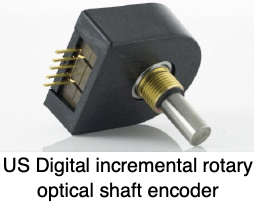

**A. Theory** 

The Quanser QUBEServo 2 is a direct drive rotary servo system. Its motor armature circuit schematic is shown in below and the electrical and mechanical parameters are given in the table. The DC motor shaft is connected to the load hub. The hub is a metal disk used to mount the disk or rotary pendulum and has a moment of inertia of Jh. A disk load is attached to the output shaft with a moment of inertia of Jd.

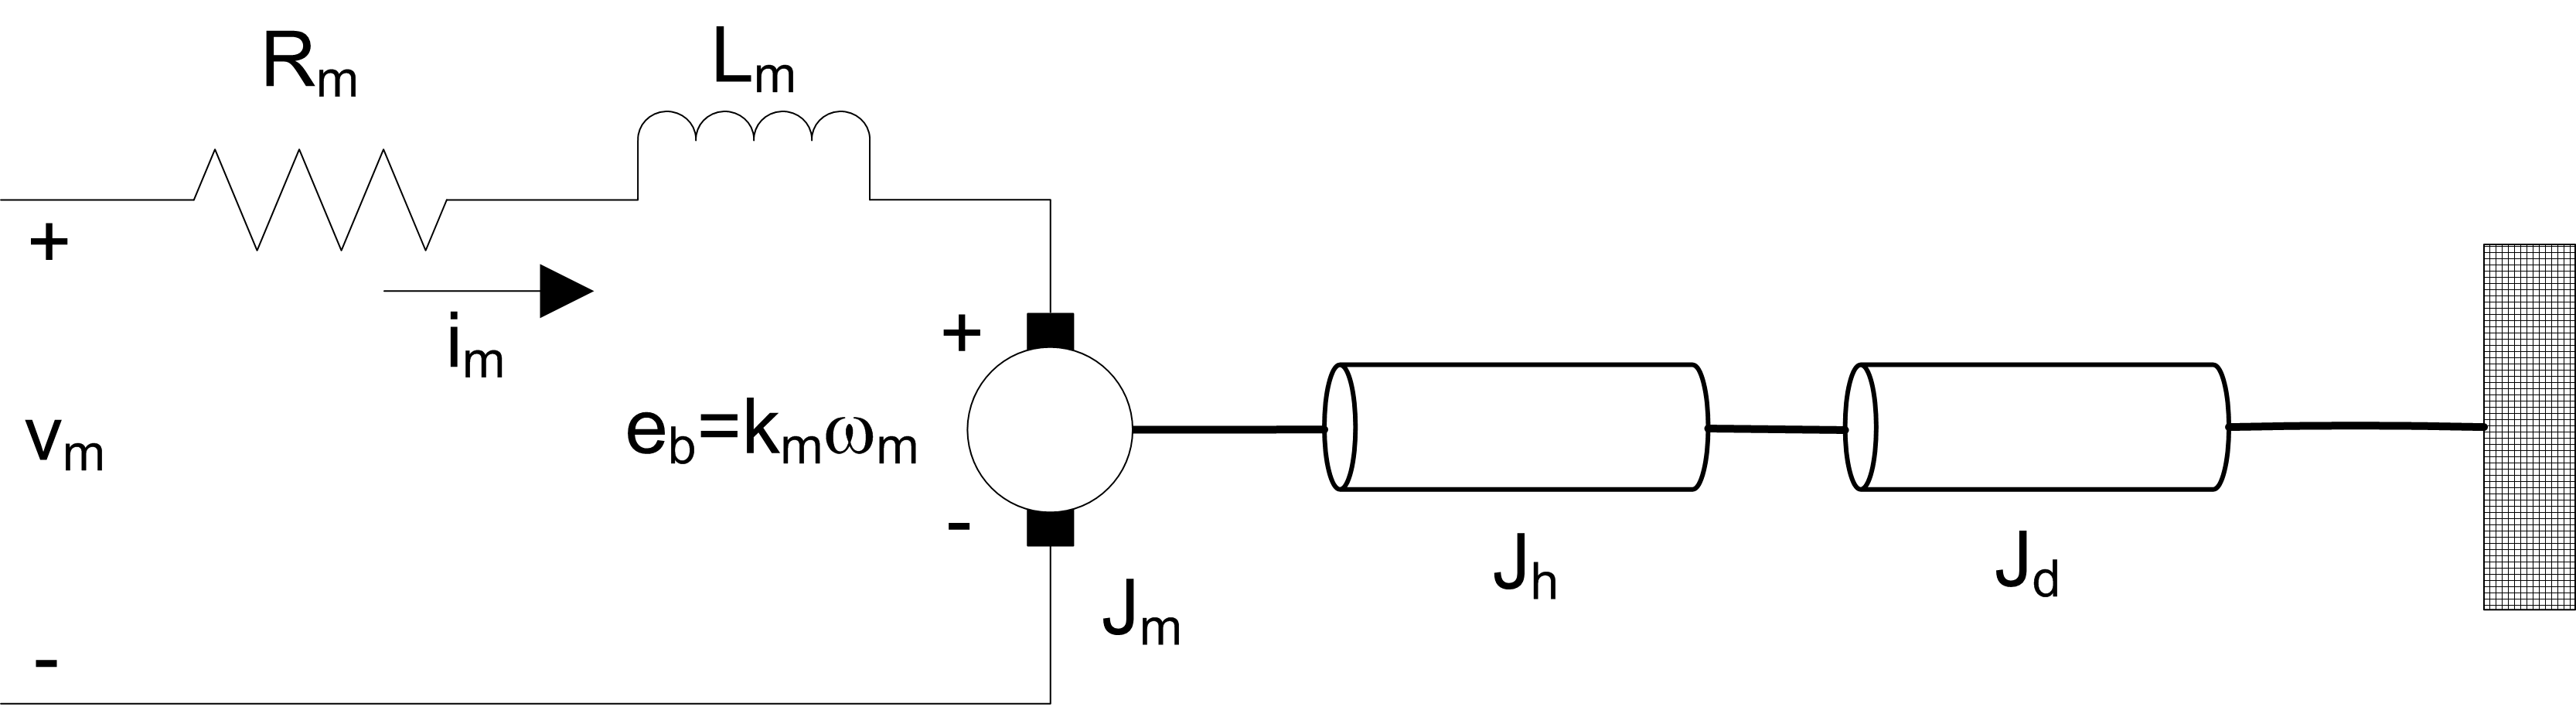

The backemf (electromotive) voltage eb(t) depends on the speed of the motor shaft, ωm, and the backemf constant of the motor, km. It opposes the current flow. The back emf voltage is given by:

$e_{b\;} \left(t\right)=k_{m\;} \omega_m \left(t\right)$     (Eq. 1)

Using Kirchoff’s Voltage Law, we can write the following equation:

$v_{m\;} \left(t\right)-R_m i_m \left(t\right)-L_m \frac{{\mathrm{di}}_m \left(t\right)}{\mathrm{dt}\;}-k_m \omega_m \left(t\right)=0$              (Eqn.2)

Since the motor inductance $L_m$ is much less than its resistance, it can be ignored. Then, the equation becomes:

$v_{m\;} \left(t\right)-R_m i_m \left(t\right)-k_m \omega_m \left(t\right)=0$        (Eqn.3)

Solving for $i_m \left(t\right)$, the motor current can be found as:

$i_m \left(t\right)=\frac{v_m \left(t\right)-k_m \omega_m \left(t\right)}{R_m }$        (Eqn.4)

The motor shaft equation is expressed as

$\begin{array}{l}
J_{\mathrm{eq}} \ddot{\theta} \left(t\right)=\tau_m \left(t\right),\;\;\;\;\mathrm{OR}\\
J_{\mathrm{eq}} \dot{\omega} \left(t\right)=\tau_m \left(t\right)
\end{array}$                    (Eqn.5)

where $J_{\mathrm{eq}}$ is total moment of inertia acting on the motor shaft and $\tau_m$ is the applied torque from the DC motor. Based on the current applied, the torque is

$\tau_m \left(t\right)=k_t i_m \left(t\right)$            (Eqn.6)

The moment of inertia of a disk about its pivot, with mass m and radius r, is

$J=\frac{1}{2\;}{\mathrm{mr}}^2$            (Eqn.7)

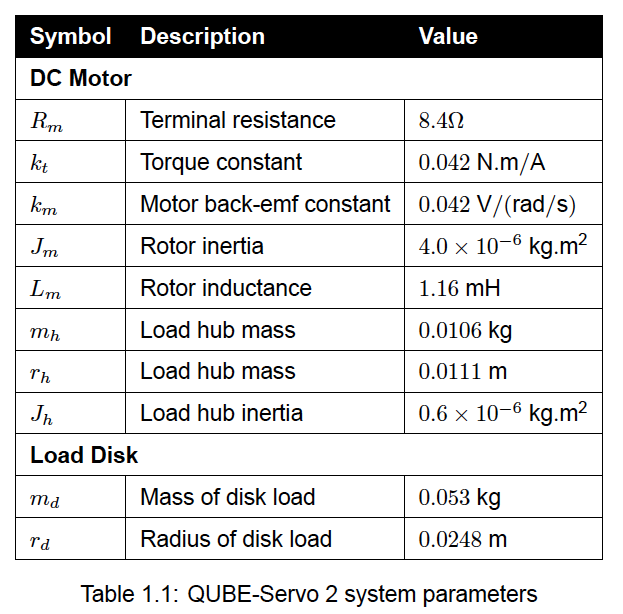

**B. The goal is to design a model that measures the servo velocity using the encoder. **

**1. Open the Simulink model shown in the above image.**

Download the files from D2L.

The applied voltage is a square wave signal that applies a 1-3V, 0.4 Hz to the motor, that's why 2  is added as a constant to the Signal Generator. 

open_system('q_qube2_studentmodel.slx')

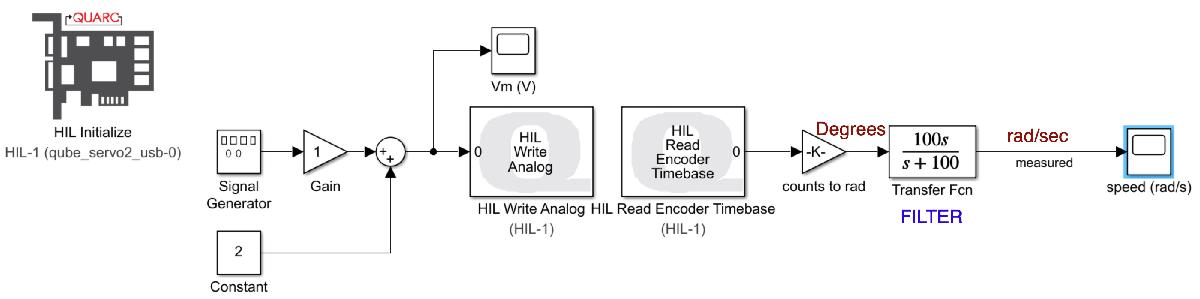

**2.** **Filter Design**

**Filtering:** A lowpass filter can be used to block out the highfrequency components of a signal. A firstorder lowpass filter

transfer function has the form: $G\left(s\right)=\frac{\omega_f }{s+\omega_f }$.

where $\omega_f$ is the cutoff frequency of the filter in radians per second. All higher frequency components of the signal will be attenuated by at least -3 dB≈ 50%.

*The s term in the numerator of the FILTER is used for taking the derivative of the angular position since we are reading angular velocity. so you can assume the transfer function of the filter is *$G_f \left(s\right)=\frac{100}{s+100}$

**2.1** Run the simulation without the filter and copy and paste the motor input and responses.

**2.2** Explain why the encoderbased measurement is noisy. 

**2.3** One way to remove some of the highfrequency components is adding a lowpass filter (LPF). 

**2.4** Show the filtered encoderbased speed response and the motor voltage. Has it improved?

**2.5** What is the cutoff frequency of the lowpass filter 100/(s + 100)? Give you answer in both rad/s and Hz.

**2.6** Vary the cutoff frequency, ωf , between 10 to 200 rad/s (or 1.6 to 32 Hz). What effect does it have on the filtered response? Consider the benefit and the tradeoff

of lowering and increasing this parameter.

**C. Modeling and Validation**

Create and add the the theoretical model using Theory, system parameters, and Simulink blocks as shown below. You need to define the system parameters before you run the simulation in Simulink.

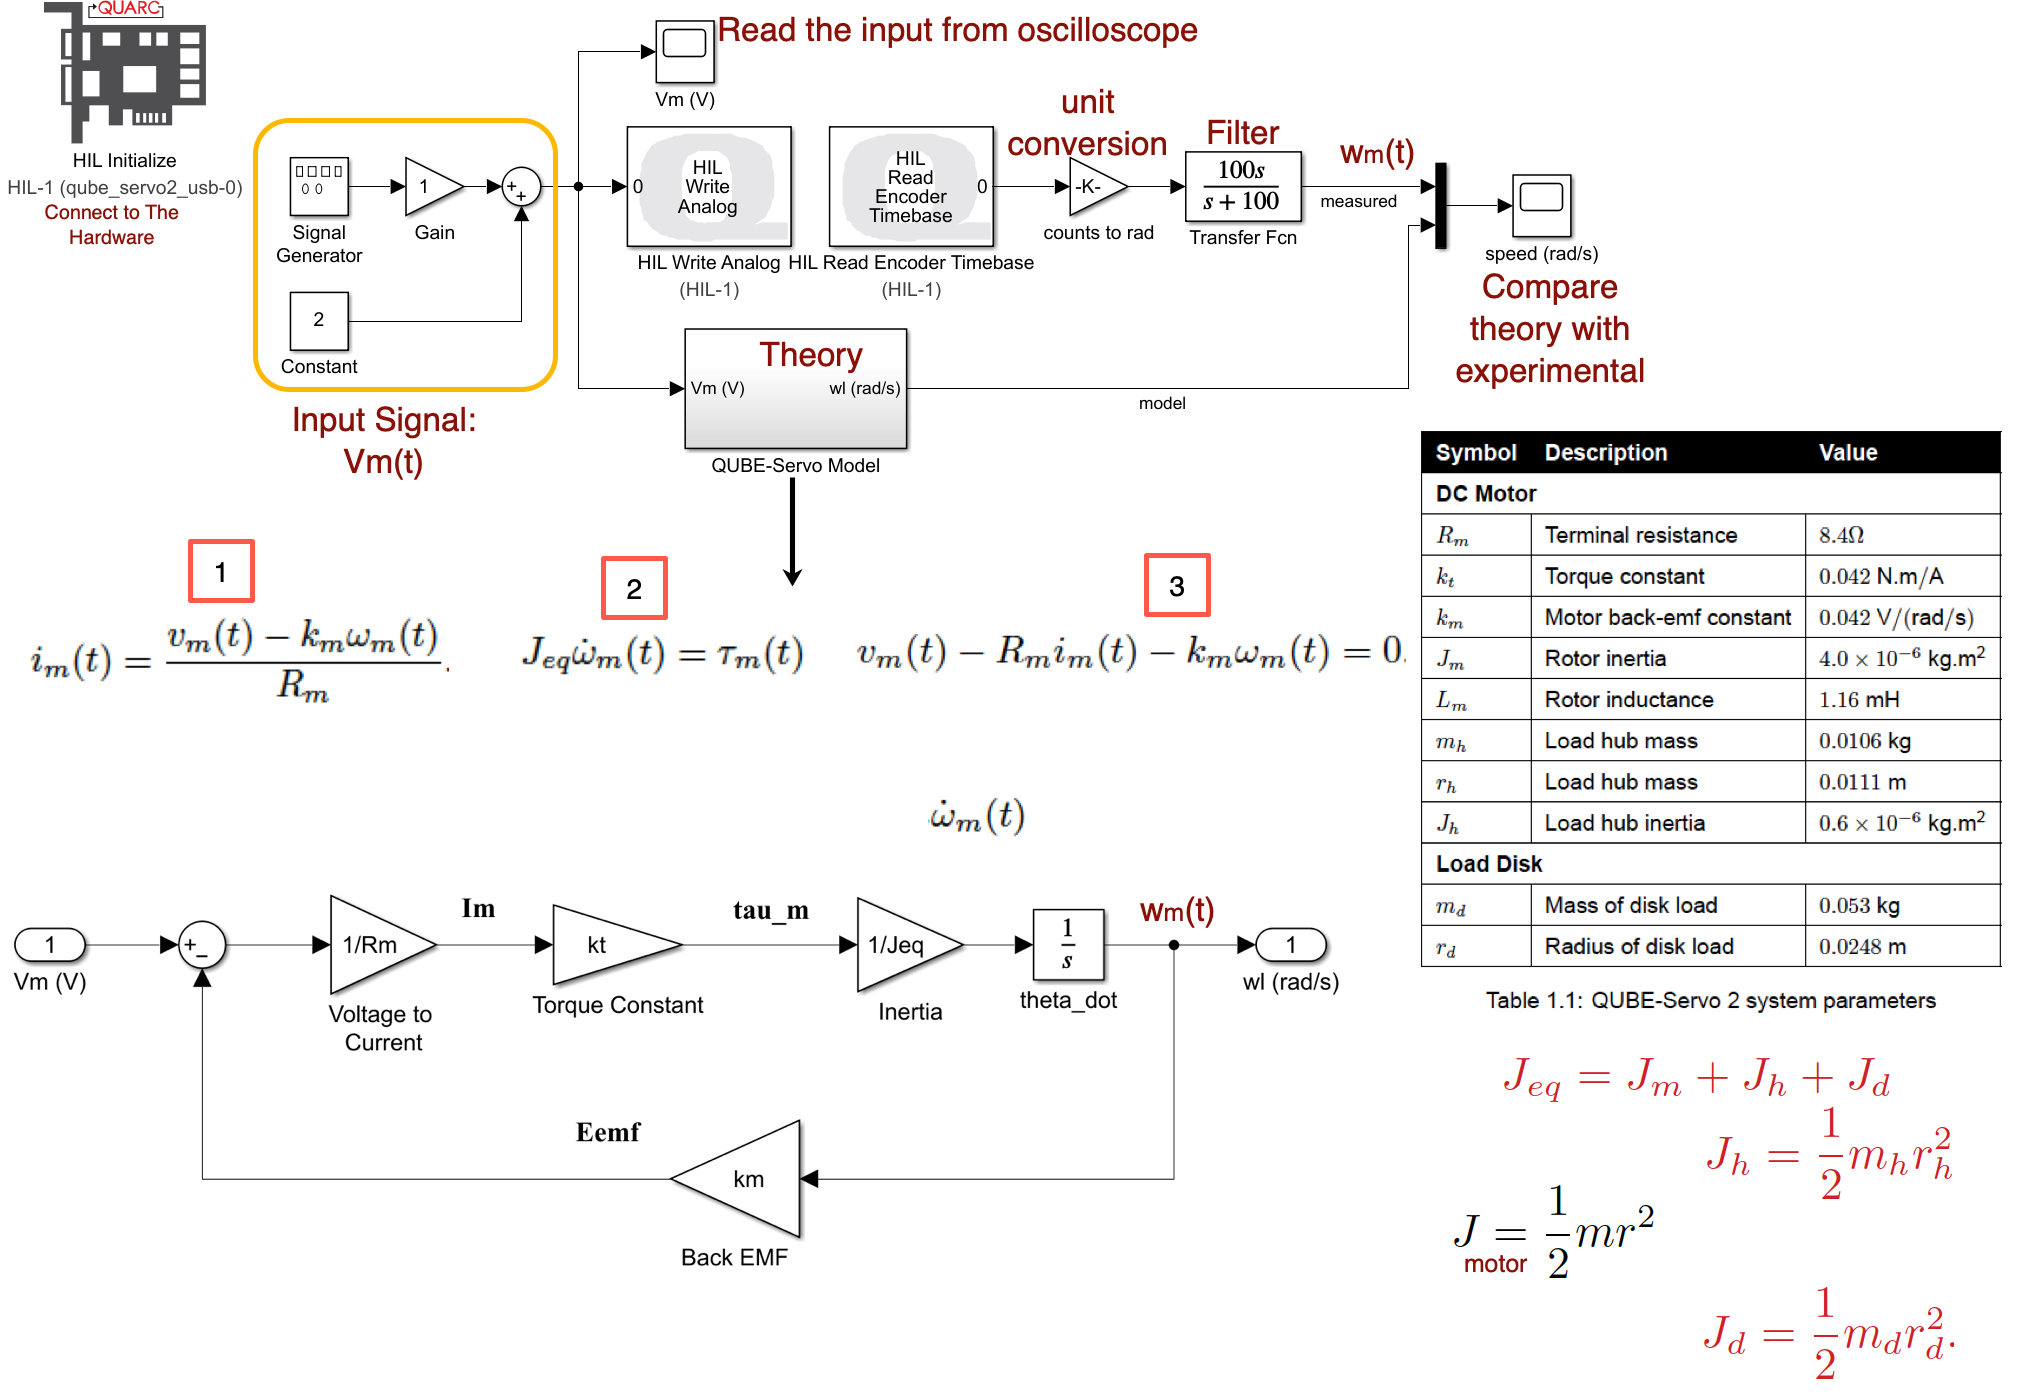

Follow the step below to able to build your model.

**1. **The motor shaft of the QUBEServo 2 is attached to a load hub and a disk load. Based on the parameters given in Table 1.1, calculate the equivalent moment of inertia that is acting on the motor shaft. Show your calculations below.

**2.** Complete the block diagram model of the QUBEServo 2 and place it the SIMULINK QUBEServo 2 Model subsystem similarly as shown in the above image. Attach a screen capture of your completed block diagram model and a MATLAB script that defines the system parameters.

**3.** Build and run the QUARC controller with your QUBEServo 2 model.  Attach a screen capture of your scopes. Does your model represent the QUBEServo 2 reasonably well?

**4.** You may notice that the the model does not match the measured system exactly. What could cause this difference? Given on possible source.

**D. Transfer Function Model**

**1. **Formulate the differential equation for $\omega_m$ using Equation 4 to Equation 6.

**2. **Take the Laplace Transform and find the voltage to speed transfer function, Ω(s)/Vm(s), of the system. Evaluate the transfer function numerically.

**3.** Attach the transfer function model to the model you created for model validation in the previous section so that you can compare the experimental, theoretical, and transfer function models. Attach a screen capture of your scopes.